## Roteiro de Laboratório – Transformada Z

### Atividade 1: Considere o seguinte sistema no domínio Z:


$$H(Z) = \frac{1 - Z^{-1}}{1 - 0.4Z^{-1} + 0.03Z^{-2}}$$


#### a) Utilize o codigo abaixo para visualizar o diagrama de zeros e polos

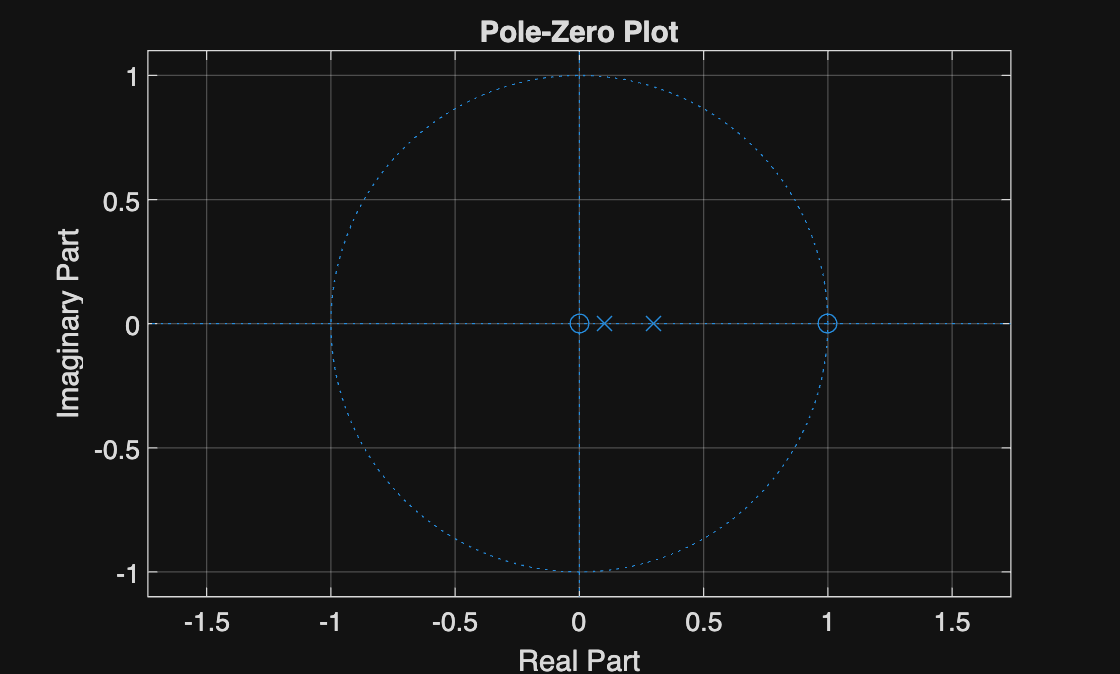

clc;
clear;
close all;
num = [1 -1];
den = [1 -0.4 0.03];
figure(1)
zplane(num,den);
grid on;

#### b) Adicione esse codigo para visualizar como fica a resposta impulsiva desse sistema no domínio tempo:

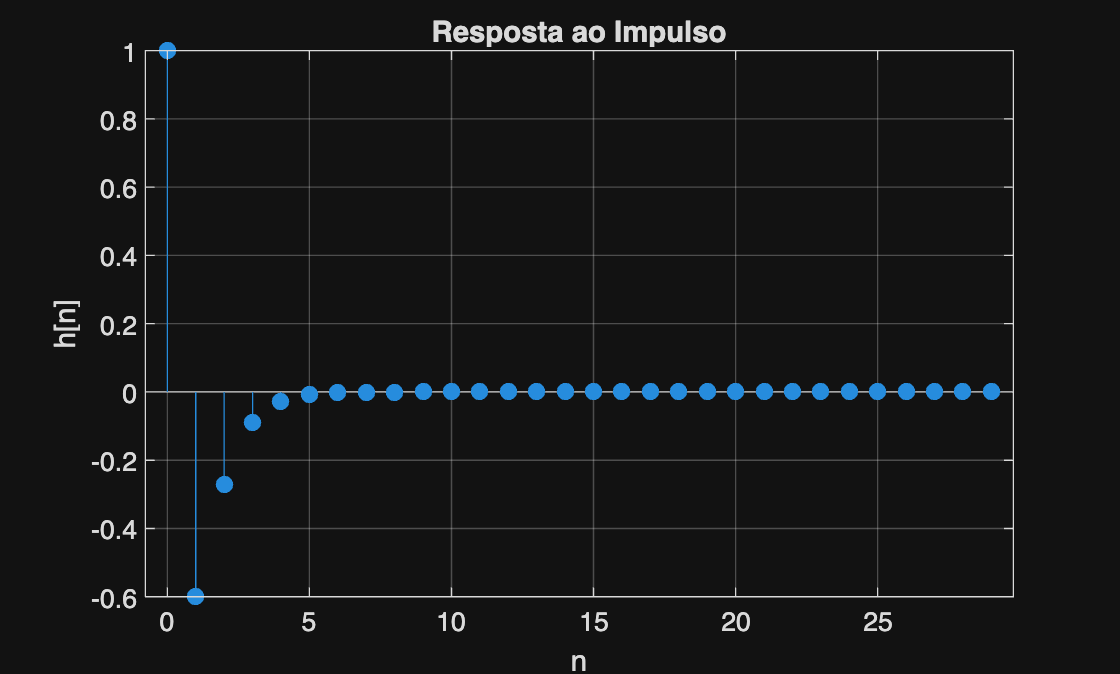

N = 30;
[h,n] = impz(num,den,N);
figure(2)
stem(n,h,'filled');
grid on;
xlabel('n');
ylabel('h[n]');
title('Resposta ao Impulso')

#### c) Adicione esse codigo para visualizar como fica a resposta desse sistema a um degrau no domí nio tempo:

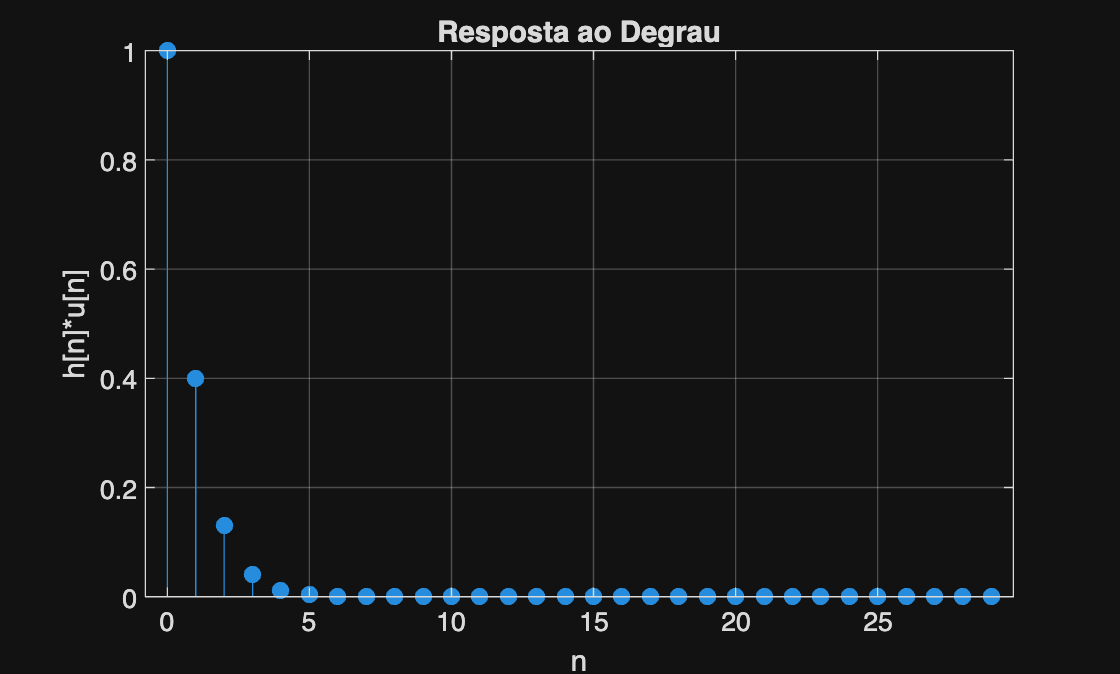

[h,n] = stepz(num,den,N);
figure(3)
stem(n,h,'filled');
grid on;
xlabel('n');
ylabel('h[n]*u[n]');
title('Resposta ao Degrau');

### Atividade 2: Para cada equaça o de diferenças abaixo, determine a representaçao de H(Z) atrave s das propriedades de linearidade e deslocamento no tempo:

*Use os comandos aprendidos na Atividade 1 para determinar a resposta ao impulso e a resposta ao degrau de cada item.

#### 
$$\text{a)} \quad 16y[n - 1] - 8y[n - 2] + y[n - 3] = -2x[n] - x[n - 1] + x[n - 2]$$



$$\begin{array}{l}
16\;z^{-1} Y\left(z\right)-8\;z^{-2} Y\left(z\right)+z^{-3} Y\left(z\right)=-2\;X\left(z\right)-z^{-1} X\left(z\right)+z^{-2} X\left(z\right)\\
Y\left(z\right)\;\left(16z^{-1} -8z^{-2} +z^{-3} \right)=X\left(z\right)\;\left(-2-z^{-1} +z^{-2} \right)\\
H\left(z\right)=\frac{Y\left(z\right)}{X\left(z\right)}=\frac{\left(-2-z^{-1} +z^{-2} \right)}{\left(16z^{-1} -8z^{-2} +z^{-3} \right)}
\end{array}$$
 


$${\,H(z)=\frac{-2\big(1-\frac{1}{2} z^{-1}\big)\big(1+z^{-1}\big)}{16\,z^{-1}\big(1-\frac14 z^{-1}\big)^{2}}\,}$$


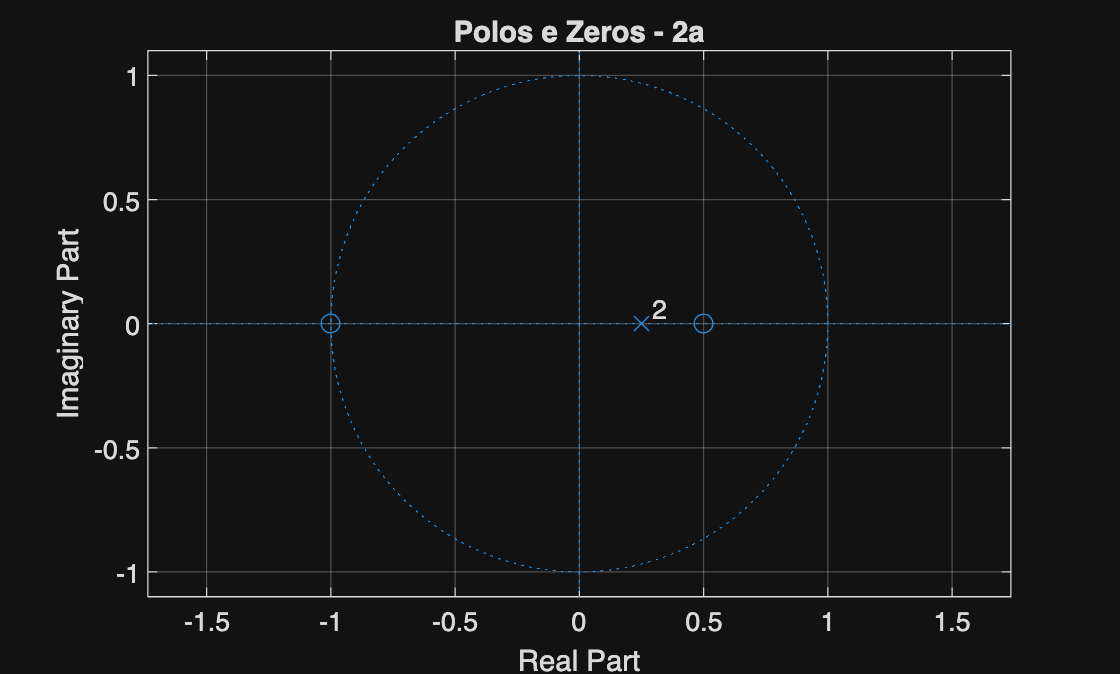

clc; clear; close all;
num = [-2 -1 1];     % -2 - z^-1 + z^-2  (de cima, igual)
den = [16 -8 1];     % parte causal: tirei o z^-1 em evidencia do denominador

% zplane aceita os dois; uso a parte causal (polos: 1/4 duplo; zeros: 1/2 e -1)
figure(1); zplane(num,den); grid on; title('Polos e Zeros - 2a');

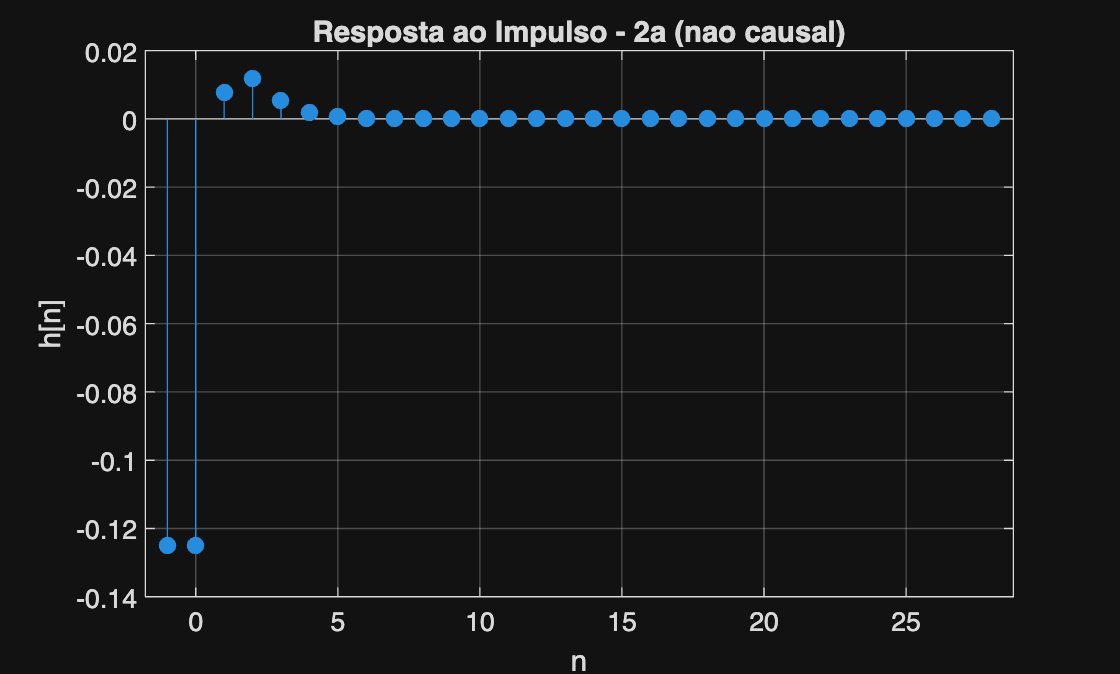


N = 30;
[g,n] = impz(num,den,N);
% o z^-1 retirado = avanco de 1: h[n] = g[n+1]  -> desloco o eixo: g(0) vira n=-1
figure(2); stem(n-1, g, 'filled'); grid on;
xlabel('n'); ylabel('h[n]'); title('Resposta ao Impulso - 2a (nao causal)');

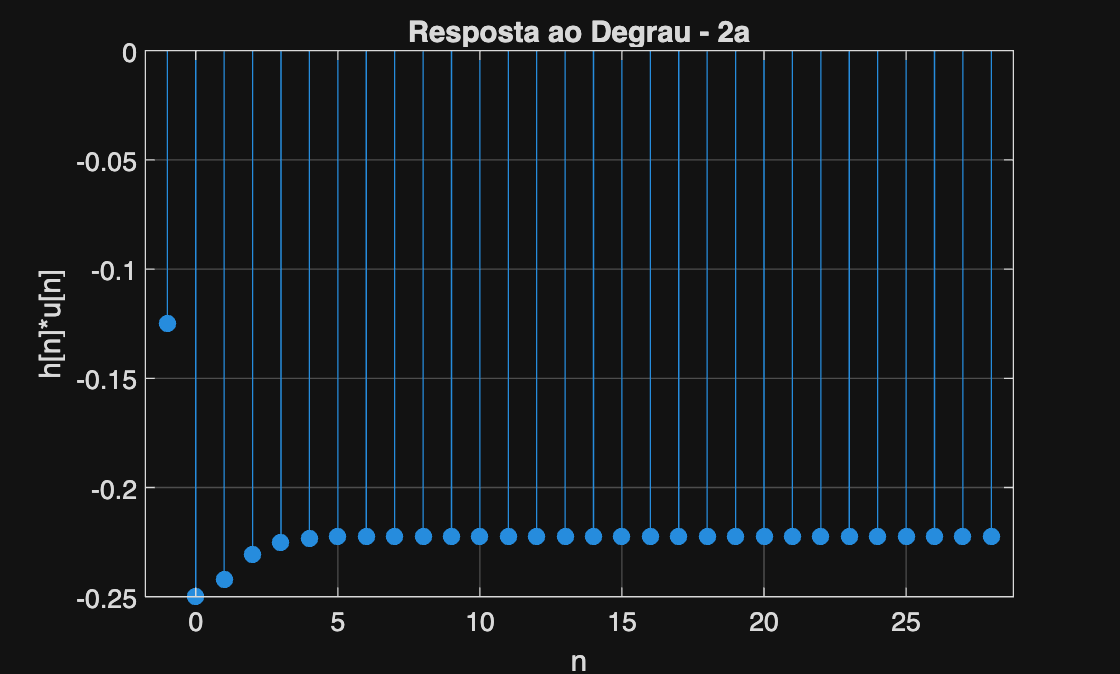


[gs,n] = stepz(num,den,N);
figure(3); stem(n-1, gs, 'filled'); grid on;
xlabel('n'); ylabel('h[n]*u[n]'); title('Resposta ao Degrau - 2a');

#### 
$$\text{b)} \quad 20y[n] - 9y[n - 1] + y[n - 2] = -8x[n] + 4x[n - 1]$$



$$\begin{array}{l}
20Y\left(z\right)-9\;z^{-1} Y\left(z\right)+z^{-2} =-8X\left(z\right)+4z^{-1} X\left(z\right)\\
Y\left(z\right)\;\left(20-9z^{-1} +z^{-2} \right)=X\left(z\right)\;\left(-8+4z^{-1} \right)\\
H\left(z\right)=\frac{Y\left(z\right)}{X\left(z\right)}=\frac{-8+4z^{-1} }{20-9z^{-1} +z^{-2} }
\end{array}$$



$${\,H(z)=\frac{-8\big(1-\frac12 z^{-1}\big)}{20\big(1-\frac14 z^{-1}\big)\big(1-\frac15 z^{-1}\big)}=\frac{-\frac25\big(1-\frac12 z^{-1}\big)}{\big(1-\frac14 z^{-1}\big)\big(1-\frac15 z^{-1}\big)}\,}$$$$


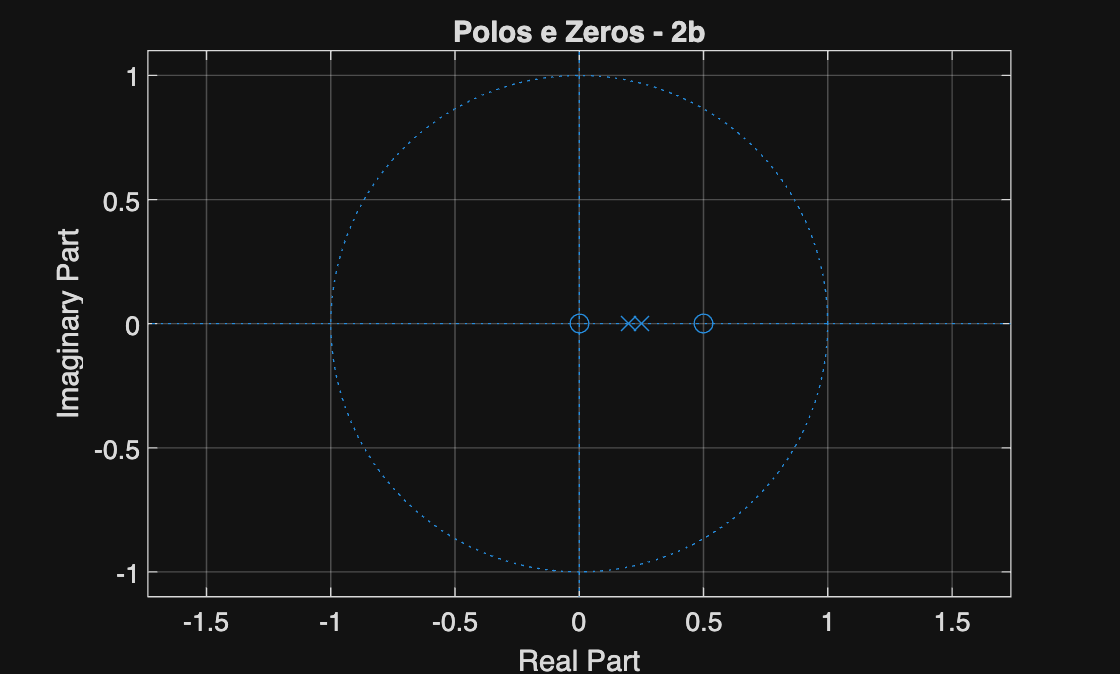

%% Atividade 2 - item b)
clc; clear; close all;
num = [-8 4];        % -8 + 4 z^-1
den = [20 -9 1];     % 20 - 9 z^-1 + z^-2
figure(1); zplane(num,den); grid on; title('Polos e Zeros - 2b');

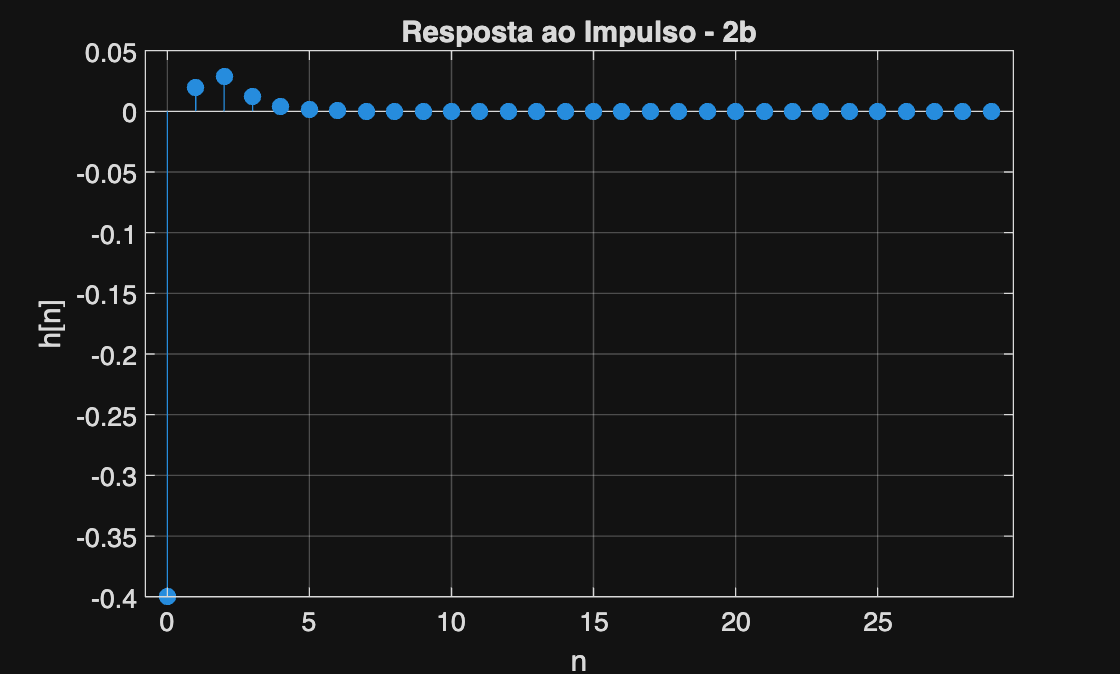


N = 30;
[h,n] = impz(num,den,N);
figure(2); stem(n,h,'filled'); grid on;
xlabel('n'); ylabel('h[n]'); title('Resposta ao Impulso - 2b');

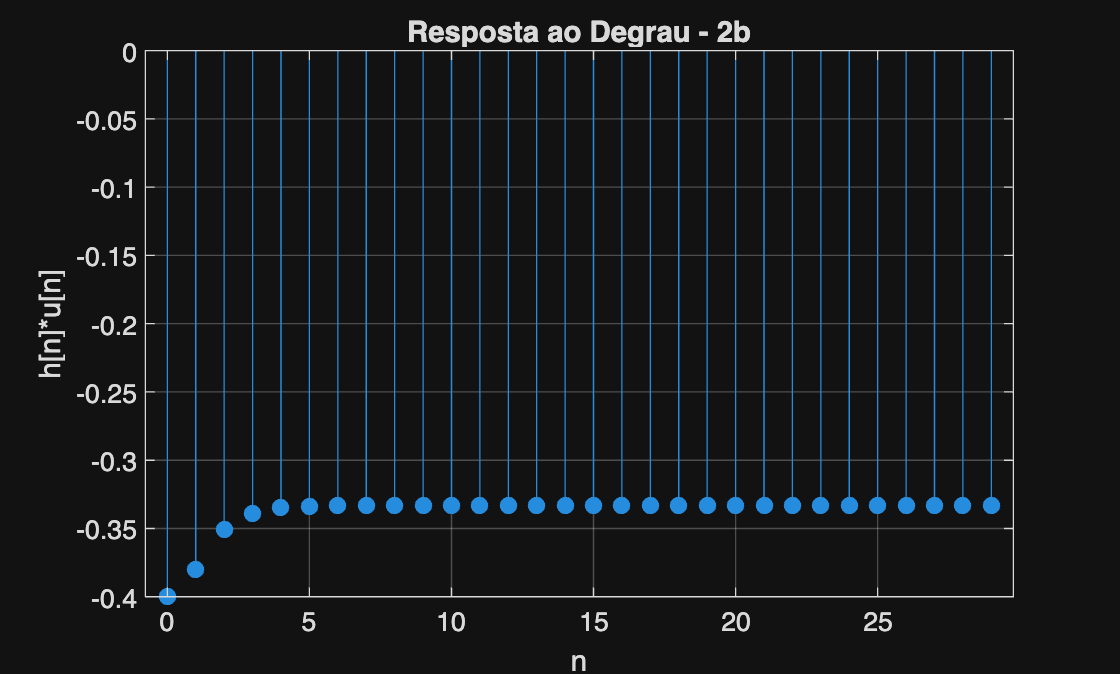


[h,n] = stepz(num,den,N);
figure(3); stem(n,h,'filled'); grid on;
xlabel('n'); ylabel('h[n]*u[n]'); title('Resposta ao Degrau - 2b');

#### 
$$\text{c)} \quad 6y[n] + 5y[n - 1] + y[n - 2] = -16x[n] + 31x[n - 1] + 28x[n - 2] + 6x[n - 3]$$



$$\begin{array}{l}
6Y\left(z\right)+5z^{-1} Y\left(z\right)+z^{-2} Y\left(z\right)=-16X\left(z\right)+31z^{-1} X\left(z\right)+28z^{-2} X\left(z\right)+6z^{-3} X\left(z\right)\\
Y\left(z\right)\left(6+5z^{-1} +z^{-2} \right)=X\left(z\right)\left(-16+31z^{-1} +28z^{-2} +6z^{-3} \right)\\
H\left(z\right)=\frac{Y\left(z\right)}{X\left(z\right)}=\frac{-16+31z^{-1} +28z^{-2} +6z^{-3} \;}{6+5z^{-1} +z^{-2} }
\end{array}$$



$${\,H(z)=\frac{-16+31z^{-1}+28z^{-2}+6z^{-3}}{6\big(1+\frac12 z^{-1}\big)\big(1+\frac13 z^{-1}\big)}\,}$$


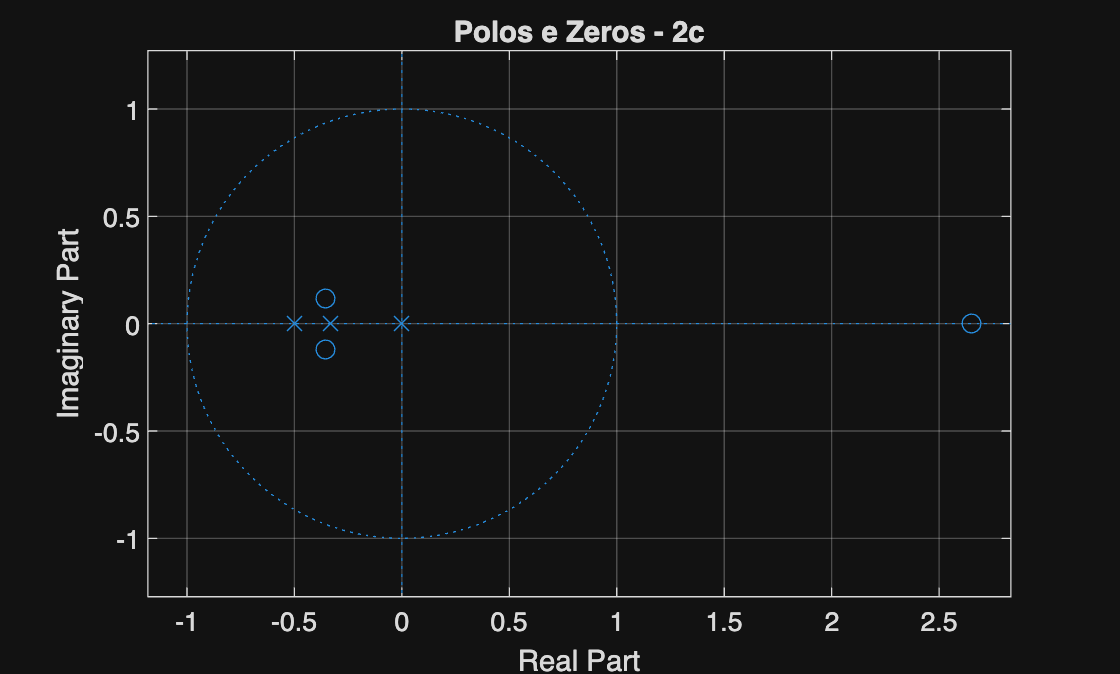

%% Atividade 2 - item c)
clc; clear; close all;
num = [-16 31 28 6];   % -16 + 31 z^-1 + 28 z^-2 + 6 z^-3
den = [6 5 1];         % 6 + 5 z^-1 + z^-2
figure(1); zplane(num,den); grid on; title('Polos e Zeros - 2c');

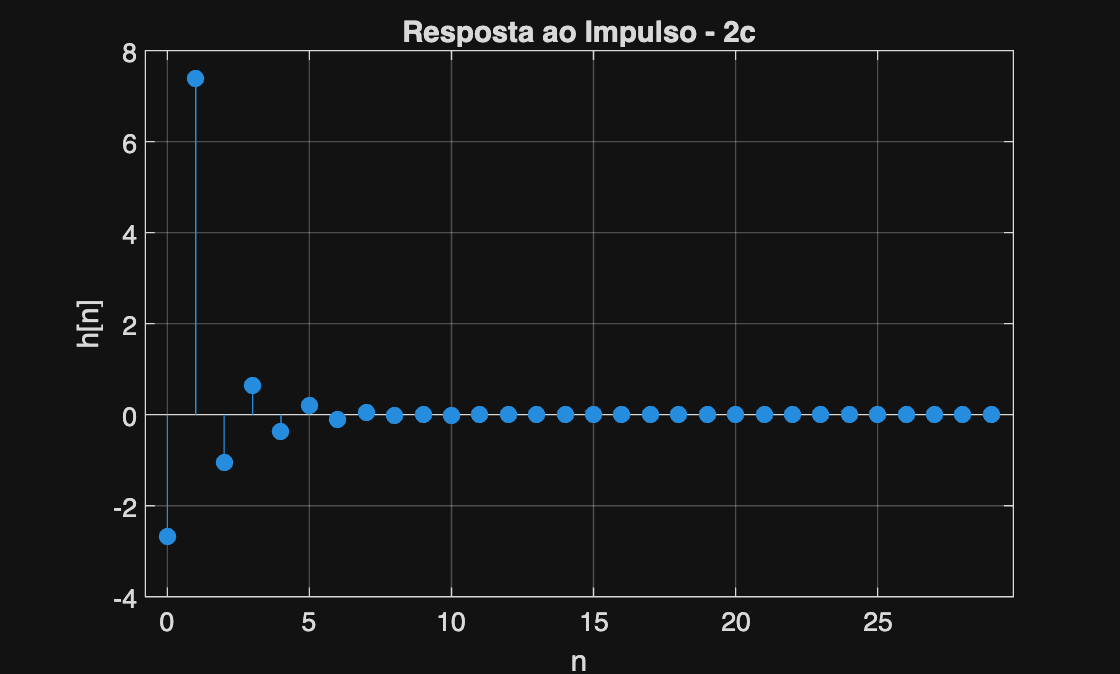


N = 30;
[h,n] = impz(num,den,N);
figure(2); stem(n,h,'filled'); grid on;
xlabel('n'); ylabel('h[n]'); title('Resposta ao Impulso - 2c');

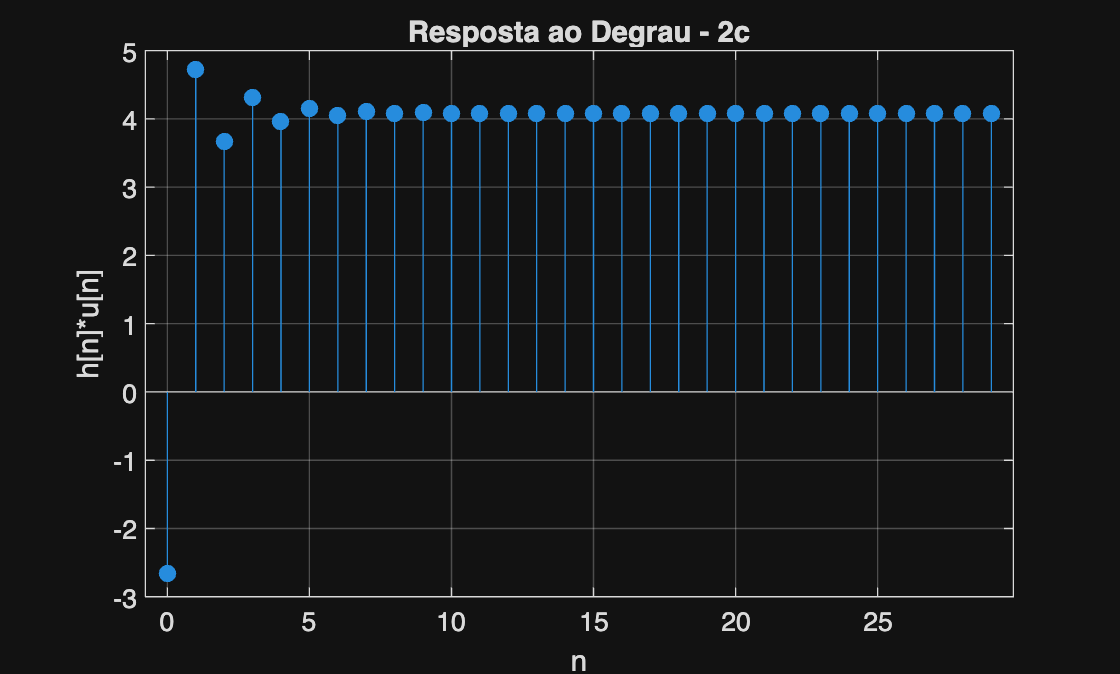


[h,n] = stepz(num,den,N);
figure(3); stem(n,h,'filled'); grid on;
xlabel('n'); ylabel('h[n]*u[n]'); title('Resposta ao Degrau - 2c');